LB 2023 12 13. I have been running this script on Turbo because it's the only working copy of leaddbs-classic that I have access to. 

SUBJECT='DM10XX';
SESSION='intraop';

% this first part of this script is not task-specific
% TASK='lombard';

PATH_DATASET = 'Y:\DBS';
% PATH_DATASET = '/Volumes/Nexus4/DBS';

PATH_DER = [PATH_DATASET filesep 'derivatives'];
PATH_DER_SUB = [PATH_DER filesep 'sub-' SUBJECT];  
PATH_PREPROC = [PATH_DER_SUB filesep 'preproc'];
PATH_ANNOT = [PATH_DER_SUB filesep 'annot'];
PATH_FREESURFER = [PATH_DER_SUB filesep 'freesurfer' filesep 'freesurfer'];
PATH_SRC = [PATH_DATASET filesep 'sourcedata'];
PATH_SRC_SUB = [PATH_SRC filesep 'sub-' SUBJECT];   
PATH_RIPPLE = [PATH_SRC_SUB filesep 'ses-intraop' filesep 'ripple'];
PATH_ANALOG = [PATH_SRC_SUB filesep 'ses-intraop' filesep 'analog'];
PATH_ALHAOMEGA = [PATH_SRC_SUB filesep 'ses-intraop' filesep 'alphaomega']; %path to neuroomega's mpx files.
PATH_ALHAOMEGA_MAT = [PATH_ALHAOMEGA]; %path to neuroomega's converted mat files.
PATH_AUDIO_DER = [PATH_DER_SUB filesep 'aec']; %path to acoustic echo cancelling folder
PATHS_AUDIO_SRC = strcat(PATH_SRC_SUB,filesep,{'ses-training';'ses-preop';'ses-intraop'},filesep,'audio');
PATHS_TASK = strcat(PATH_SRC_SUB,filesep,{'ses-training';'ses-preop';'ses-intraop'},filesep,'task');

paths = {[PATH_DATASET '/derivatives/sub-' SUBJECT '/Herrington_leaddbs_refined'], 
        [PATH_DATASET '/derivatives/sub-' SUBJECT '/Herrington_leaddbs'], 
        [PATH_DATASET '/derivatives/sub-' SUBJECT '/leaddbs']};
for ip = 1:numel(paths); if isfolder(paths{ip}); PATH_LEADDBS = paths{ip}; disp(PATH_LEADDBS); break; end; end 
cd(PATH_PREPROC)

PATH_ECOGLOC = [PATH_DER_SUB filesep 'ecogloc'];
mkdir(PATH_ECOGLOC)
path_preopct_coreg = [PATH_ECOGLOC filesep 'leaddbs_coreg_preopct2preopmri']; mkdir(path_preopct_coreg)

Copy T1 MRI from the leaddbs folder. We also copy raw_anat_t1 because otherwise leaddbs might shift or reslice anat_t1, resulting in misalignment of preop and postop CTs. 

copyfile([PATH_LEADDBS filesep 'anat_t1.nii'], [path_preopct_coreg filesep 'anat_t1.nii']); 
copyfile([PATH_LEADDBS filesep 'raw_anat_t1.nii'], [path_preopct_coreg filesep 'raw_anat_t1.nii']); 

Copy preop ct from sourcedata. This path might need to be tweaked.  

copyfile([PATH_SRC_SUB filesep 'ses-intraop' filesep 'ct' filesep ...
               'sub-' SUBJECT '_006_0.6_Soft_PRE_OP_Brain_DBS_FUNCTIONAL_.nii'], ... % AM appended 'sub-' 2025/4/30 
         [path_preopct_coreg filesep 'postop_ct.nii']); 

% 2025/4/30 AM added the following 4 lines to add leaddbs classic to the path if you're on Turbo
computerName = getenv('COMPUTERNAME')
if strcmp (computerName, 'NSSBML01')
    addpath(genpath('C:\Program Files\LeadDBS_Classic\leaddbs'))
end

which lead_dbs

^Ensure this says LeadDBS_Classic. This step has only been verified with the 'classic' (<v2.6, non-bids) version of lead-dbs. If it does not, remove the current Lead-DBS from your path and add a classic version. 

Open the lead_dbs gui. 

- Click 'choose patient directory' and navigate to the leaddbs_coreg_preopct2preopmri folder created above. The folder is named derivatives/sub-{subject-id}/ecogloc/leaddbs_coreg_preopct2preopmri

- Check the 'coregister volumes' box and click 'Run'. 

lead_dbs

Copy the registered preop/intraop CT (unfortunately called 'rpostop_ct.nii') into the ecogloc folder.  

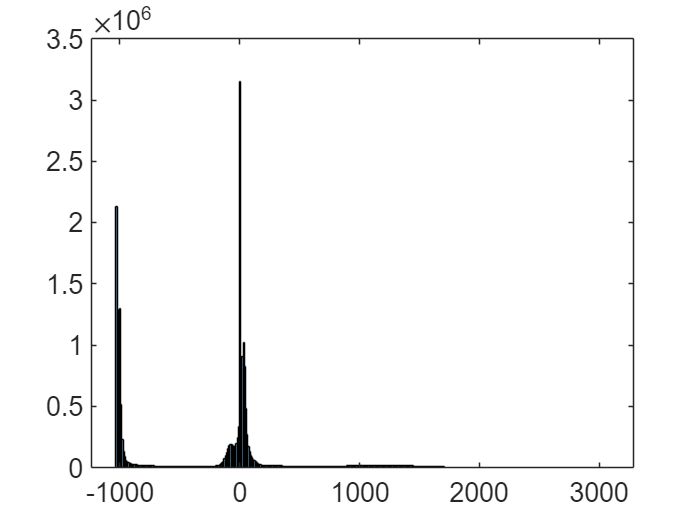

copyfile([PATH_LEADDBS filesep 'anat_t1.nii'], [PATH_ECOGLOC filesep 'preop_mri.nii']); 
copyfile([PATH_LEADDBS filesep 'rpostop_ct.nii'], [PATH_ECOGLOC filesep 'rpostop_ct.nii']);

% rpostop_ct.nii is actually the PRE-OP CT. It's called postop because

% that's what leaddbs expectts. We copy it to ecogloc as rpreop_ct.nii
copyfile([path_preopct_coreg filesep 'rpostop_ct.nii'], [PATH_ECOGLOC filesep 'rpreop_ct.nii']);

Check that lead_dbs successfully co-registered the pre-op ct with your favorite imaging software (ITK-SNAP, slicer, etc).

LB 2023 12 13. I usually open the three files in ITK-SNAP--first the MRI, then the preop CT, then the postop CT. I check that the images are in alignment, that the preop CT is indeed the preop CT by looking for the frame artifacts. I also check the postop CT has DBS artifacts. 

In the image below for DM1024, I'm overlaying the postop CT in red over the preop CT in greyscale. There is some misalignment at the back of the skull in the sagittal slice.  

**Save a screenshot of ITK-SNAP with pre and post-op overlaid on each other to ecogloc/sub-<id>-ses-intraop_coreg-verification.png**

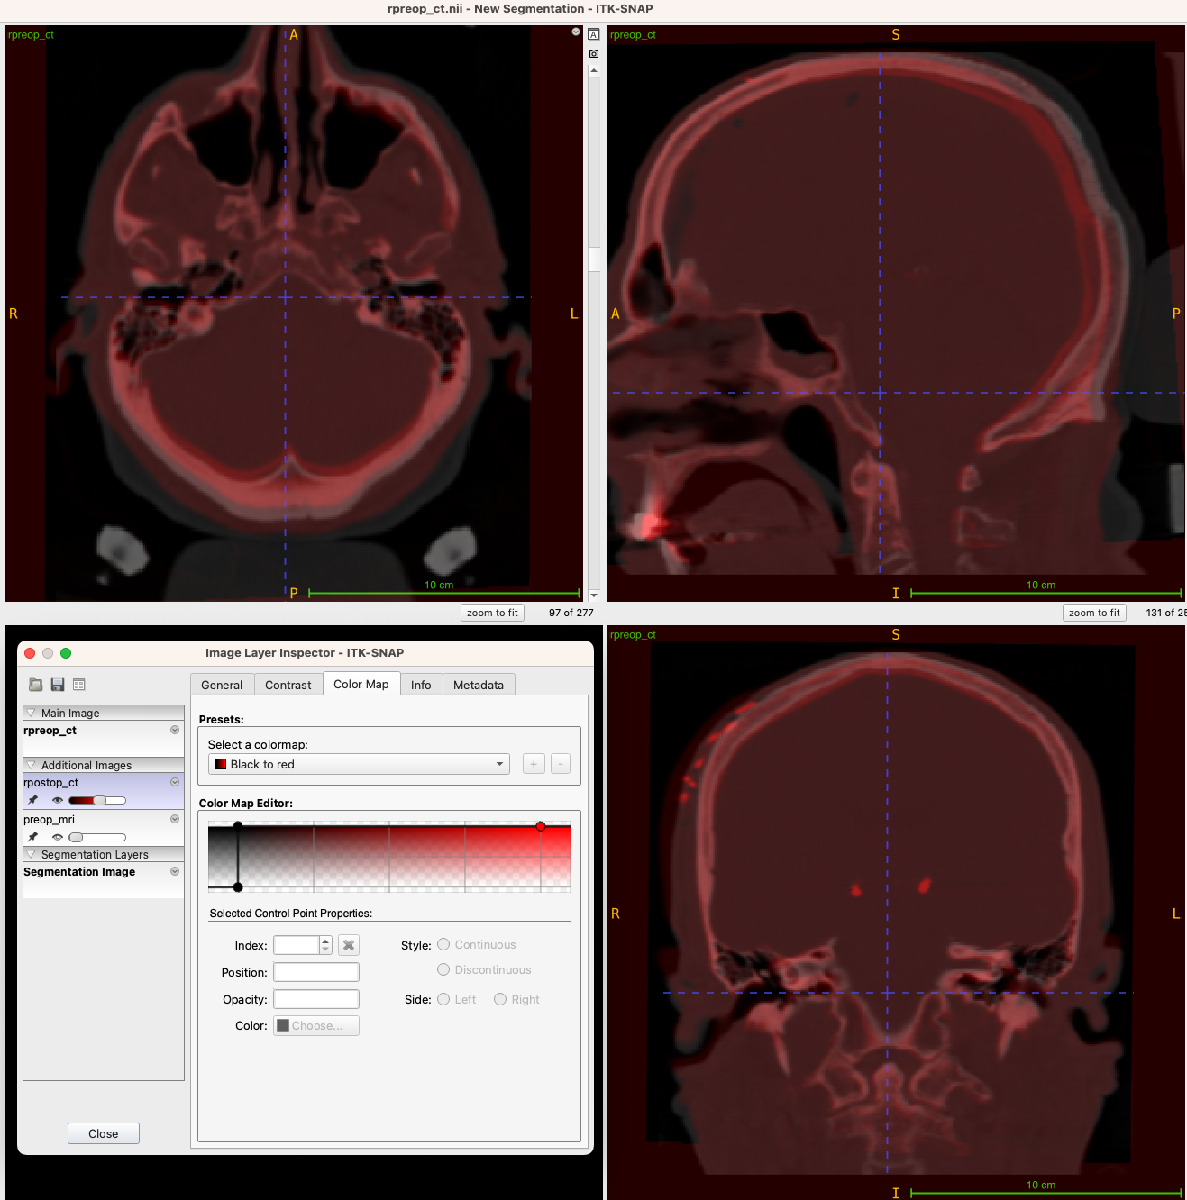

Generate a 3d surface model of the skull from the preop CT. 

V=spm_vol([PATH_ECOGLOC filesep 'rpreop_ct.nii']);
[I, XYZ]=spm_read_vols(V);

figure; histogram(I(:))
s = size(I); 
fv = isosurface(reshape(XYZ(1, :), s), ...
                reshape(XYZ(2, :), s), ...
                reshape(XYZ(3, :), s), ...
                I, ...
                -200); 
fvr = reducepatch(fv, 0.5); % reduced faces and vertices

skull = []; 
skull.vert = fvr.vertices; 
skull.tri = fvr.faces; 
save([PATH_FREESURFER filesep 'skull.mat'], 'skull'); 

%% visualize reconstruction
plotfv = fvr; 
figure; patch('faces', plotfv.faces, 'vertices', plotfv.vertices,...
    'facecolor',[.65 .65 .65],'edgecolor','none',...
    'facelighting', 'gouraud', 'specularstrength', .25);

camlight('headlight','infinite');
axis equal